% This code was generated via ChatGPT 5.4 ("extended thinking").


## F-16A Level 1 Sizing Analysis — Class-Based Example

% This live script performs a Level 1 sizing pass for the F-16A example using
% the toolkit classes supplied with the project.
%
% Main objects used:
%   * AircraftDesign
%   * GeometryLevel1
%   * AeroLevel1
%   * PropulsionLevel1
%   * WeightLevel1
%   * MissionAnalysisLevel1
%   * ConstraintAnalysisClass
%   * Requirements
%   * SizingClassLevel1
%
% The script assumes the corresponding class files, import utilities, design
% workbook, requirements table, constraints table, and mission profile are on
% the MATLAB path.

% clear; clc; close all;

%% Project setup
% Set this to the folder containing your classes, import utilities, design
% spreadsheet/workbook, requirements file, constraints file, and mission data.
projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";


## Create the aircraft design object

% AircraftDesign is the project-level object. It imports the design geometry,
% fuselage data, propulsion data, weight data, general aircraft data, and
% requirements reference.

design = AircraftDesign( ...
     designName, ...
     RequirementsName = requirementsName, ...
     ConstraintsName  = constraintsName, ...
     AutoLoad         = true);


% Keep the constraints filename explicit in case the design constructor was
% given a blank or nonstandard value.
if strlength(string(design.constraints_filename)) == 0
     design.constraints_filename = constraintsName;
end

disp("AircraftDesign object created:")

AircraftDesign object created:


disp(design)

  AircraftDesign with properties:

                     Name: "F-16A Block 50"
                     geom: [1×1 struct]
                  general: [1×1 struct]
               propulsion: [1×1 struct]
          propulsion_type: "low bpr turbofan"
                n_engines: []
                 CivOrMil: []
                     role: []
                  weights: [1×1 struct]
                     type: "Jet fighter"
              wing_config: []
              tail_config: []
            fuselage_type: []
               nose_shape: []
             requirements: [1×1 struct]
    requirements_filename: []
     constraints_filename: "Constraints"
            WeightResults: []
              AeroResults: []
        PropulsionResults: []
           internalvolume: []


## Build the Level 1 analysis objects

% These objects are intentionally lower-fidelity than the Level 3 versions.
% They rely on historical estimates, tabulated assumptions, and simple mission
% weight fractions/Breguet-style estimates.

geometry_obj     = F16GeometryLevel1(design);
weight_obj       = F16WeightLevel1(design);
aero_obj         = F16AeroLevel1("jet fighter", geometry_obj, weight_obj);
propulsion_obj   = F16PropulsionLevel1(design);
mission_obj      = F16MissionAnalysisLevel1(missionName);
constraint_obj   = ConstraintAnalysisClass(design);

requirements_obj = Requirements(design);
sizing_obj       = F16SizingLevel1();


% Compute required constraints
constraint_obj.constraint_analysis;

## Run the project sizing class

% OLD COMMENT IGNORE THIS
% This calls the F16SizingLevel1 method directly. The method returns the
% converged W_TO. In the current class definition, results_table is assigned
% inside the method, but the class itself does not inherit handle, so the table
% may not persist outside the method depending on your inheritance tree.
% OLD COMMENT IGNORE THIS

tol = 1e-3;
max_iteration = 40;
results = [];

LD_max = aero_obj.LD_max;
W_fixed = weight_obj.W_fixed;

W_S = constraint_obj.optimal_WS;
T_W = constraint_obj.min_TW;

W_TO = weight_obj.W_TO_guess;

for iteration = 1:max_iteration
     S_ref = W_TO/W_S;

     [weight_obj.total_fuel_used, weight_obj.fuel_fraction] = mission_obj.get_mission_fuel(propulsion_obj, W_TO, LD_max);
     weight_obj.OEW = weight_obj.get_OEW(design.type, W_TO);
     weight_obj.OEW_frac = weight_obj.OEW/W_TO;

     W_TO_new = sizing_obj.size_aircraft(weight_obj.OEW, weight_obj.total_fuel_used, W_fixed);
     difference = W_TO_new - W_TO;
     percent_diff = 100 * difference/W_TO;

     results(end+1, :) = [W_TO, W_fixed, weight_obj.fuel_fraction, weight_obj.OEW_frac, weight_obj.OEW, W_TO_new, difference, percent_diff, S_ref];

     if abs(difference) < tol
          break;
     end
     W_TO = W_TO_new;
     T0 = T_W*W_TO;
end
weight_obj.W_TO = W_TO;
sizing_obj.results_table = array2table(results, 'VariableNames', {'WTO', 'W_fixed', 'Fuel_fraction', 'Empty_weight_fraction', 'Empty_weight', 'WTO_new', 'Difference', 'Percent_Diff', 'S_ref'});
obj.results_table = results_table;
W_TO_final = W_TO_new;
sizing_output = sizing_obj.results_table;
disp(sizing_output);

     WTO     W_fixed    Fuel_fraction    Empty_weight_fraction    Empty_weight    WTO_new    Difference    Percent_Diff    S_ref 
    _____    _______    _____________    _____________________    ____________    _______    __________    ____________    ______
    45000     5100         0.25039              0.58116              26152         41882       -3117.9         -6.9286     405.41
    41882     5100         0.24985              0.58661              24569         39541       -2341.4         -5.5904     377.32
    39541     5100          0.2494              0.59102              23369         37772       -1768.4         -4.4722     356.22
    37772     5100         0.24901          

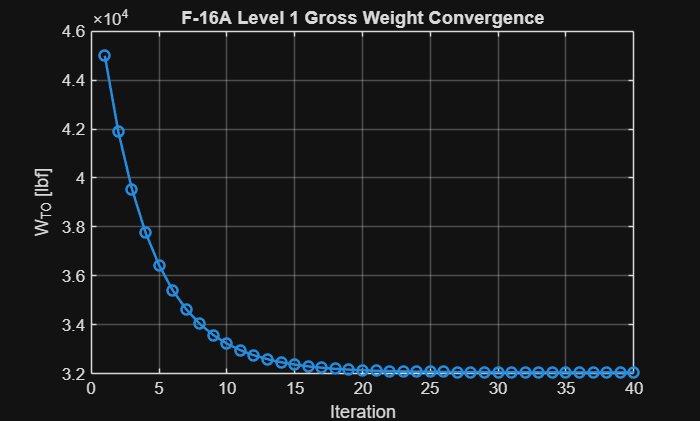


propulsion_obj.T0 = T0;

figure('Name', 'Level 1 Gross Weight Convergence');
plot(1:height(sizing_obj.results_table.WTO), sizing_obj.results_table.WTO, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 1 Gross Weight Convergence');

## Plot closure error

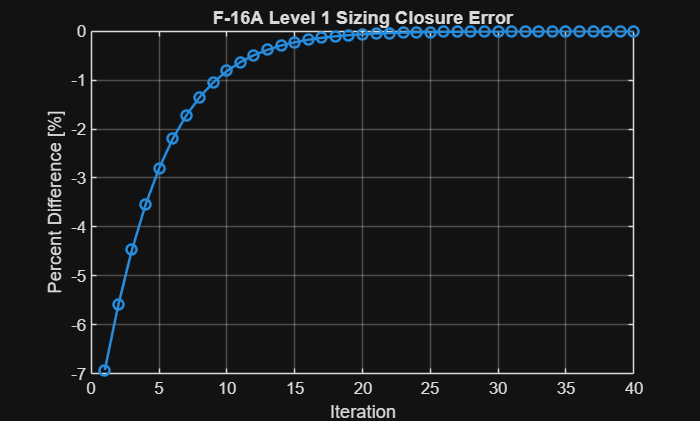

figure('Name', 'Level 1 Closure Error');
plot(1:height(sizing_obj.results_table.WTO), sizing_obj.results_table.Percent_Diff, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 1 Sizing Closure Error');

## Plot final weight breakdown

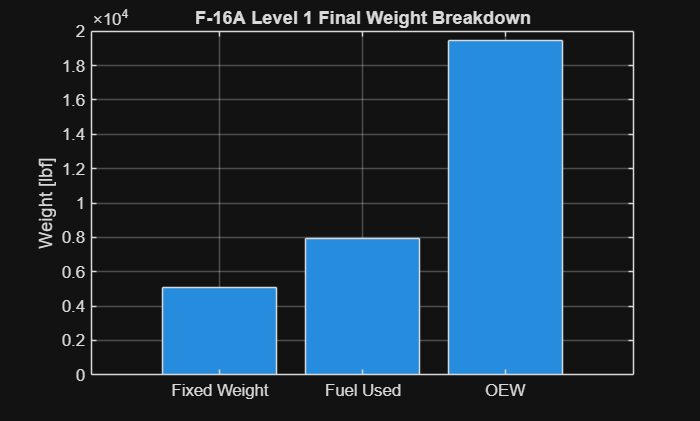

weightBreakdown = table( ...
     categorical(["OEW"; "Fuel Used"; "Fixed Weight"]), ...
     [sizing_output.Empty_weight(length(sizing_output.WTO)); ...
     sizing_output.Fuel_fraction(length(sizing_output.WTO)).*sizing_output.WTO(length(sizing_output.WTO)); ...
     sizing_output.W_fixed(length(sizing_output.WTO))], ...
     'VariableNames', {'Component', 'Weight_lbf'});

figure('Name', 'Level 1 Final Weight Breakdown');
bar(weightBreakdown.Component, weightBreakdown.Weight_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 1 Final Weight Breakdown');

## Save results into the AircraftDesign object

% % AircraftDesign is a handle class, so these assignments persist on the design
% % object during this MATLAB session.
%
design.WeightResults.Level1SizingTable = sizing_output;
design.WeightResults.W_TO              = sizing_output.WTO(length(sizing_output.WTO));
design.WeightResults.OEW               = sizing_output.Empty_weight(length(sizing_output.WTO));
design.WeightResults.FuelUsed          = sizing_output.Fuel_fraction(length(sizing_output.WTO)).*sizing_output.WTO(length(sizing_output.WTO));

design.AeroResults.Level1.LDmax         = aero_obj.LD_max;
design.AeroResults.Level1.AR_wetted     = aero_obj.AR_wet;
design.AeroResults.Level1.S_wet         = geometry_obj.design.S_wet;

design.PropulsionResults.Level1.T0      = propulsion_obj.T0;
design.PropulsionResults.Level1.TSFC    = propulsion_obj.TSFC;